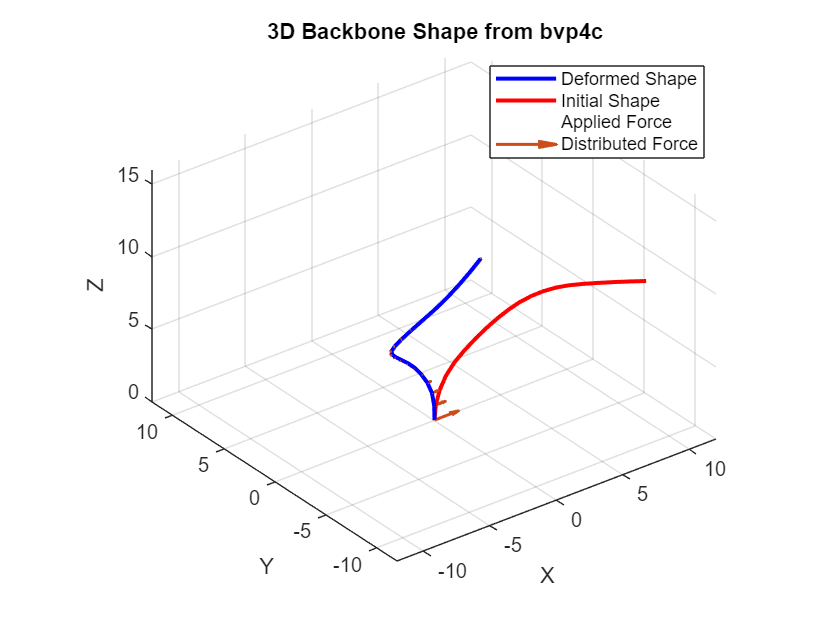

%This is a test file for beam bending simulation

%TODO:
%Implementing distributed force
%Implementing multiple segments

clear, close all

% Parameters
EI = 1;         % Bending stiffness
GJ = .7;
r = 5 / pi;        % Robot radius
n = 1;             % Number of segments
N = 5;         % Number of discretization points
N_d = 5;            % Number of points to estimate distributed force



% Initial actuator positions
act_11_start = [r; 0; 0; 1];
act_12_start = [r*cos(2*pi/3); r*sin(2*pi/3); 0; 1];
act_13_start = [r*cos(4*pi/3); r*sin(4*pi/3); 0; 1];
Base_coord = eye(4);


%Force applied at tip, N
Fx = 0.00; 
Fy = 0.00; 
Fz = 0.00;

%Moment applied at tip
Mx = 0;
My = 0;
Mz = 0;

%Actuator Lengths
m = 4;

L1 = [4,5,5,4];
L2 = [5,4,5,5];
L3 = [6,5,6,5];


L1_act = [3.8,4.5,4.3,4.2];
L2_act = [5.1,4.6,5.5,5.1];
L3_act = [6.1,4.9,6.2,4.7];

Lck = sum((L1+L2+L3))/3;

%Turn plot on or off
ploton = false;


simple_f = @(s) [0*s; 0*s; 0*s];  % No dist force
dist_f = @(s) [.3*1/(s+1)*cos(2*pi*s/Lck); .00;0 ];  % gravity in -Z
s_force = linspace(0, Lck, N); % same arc length as beam
s_force_d = linspace(0, Lck, N_d);  % force estimation points
%Input function for testing
[p_def,p_init] = bending_3D(EI,GJ,r,N,m,L1,L2,L3,Base_coord,Fx,Fy,Fz,Mx,My,Mz,s_force,dist_f,true);

%[p_def,p_init] = bending_3D(EI,GJ,r,N,L1,L2,L3,act_11_start,act_12_start,act_13_start,Base_coord,.03,0,-.04,Mx,My,Mz,s_force,simple_f,true);





%For now, I will use the function twice to generate two sets of points for
%two sensed actuator length sets

[p_pred,~] = bending_3D(EI,GJ,r,N,m,L1,L2,L3,Base_coord,0,0,0,Mx,My,Mz,s_force,simple_f,ploton);

[p_act,~] = bending_3D(EI,GJ,r,N,m,L1_act,L2_act,L3_act,Base_coord,0,0,0,Mx,My,Mz,s_force,simple_f,ploton);


lambda = .1;                   % regularization weight


% Observed shape
p_target = p_act;

fun = @(x) objective_with_reg_Nd(x, p_target, EI, GJ, r, N, m,N_d, ...
            L1, L2, L3, ...
            Base_coord, Mx, My, Mz, s_force_d, s_force, lambda);
%Given input xdata and observed output ydata, find x
%x0 = [0; 0; 0];

x0 = 0.00*randn(3*N_d, 1);

lb = -1*ones(3*N_d,1);
ub = 1*ones(3*N_d,1);
% Fix base force components to zero:
lb(1:3) = 0;
ub(1:3) = 0;


options = optimoptions(@lsqnonlin, ...
    'Algorithm', 'trust-region-reflective', ...
    'MaxIterations', 5, ...
    'Display', 'iter-detailed', ...
    'StepTolerance', 1e-3, ...
    'FunctionTolerance', 1e-1, ...
    'FiniteDifferenceType', 'forward', ...
    'SpecifyObjectiveGradient', false); 

tic
% Solve

x_est = lsqnonlin(fun, x0, lb, ub, options);


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0         13           349.142                         2.48e+05
     1         26           349.142      0.00503913         2.48e+05      
     2         39            6.6341      0.00125978         1.16e+04      
     3         52           4.02232      0.00251957         2.52e+03      
     4         65            1.8741      0.00503913         1.78e+03      
     5         78          0.493327      0.00905027          5.9e+03      
     6         91         0.0660743      0.00447762              461      

Solver stopped prematurely.

lsqnonlin stopped because it exceeded the iteration limit,
options.MaxIterations = 5.000000e+00.



toc

Elapsed time is 11.700459 seconds.


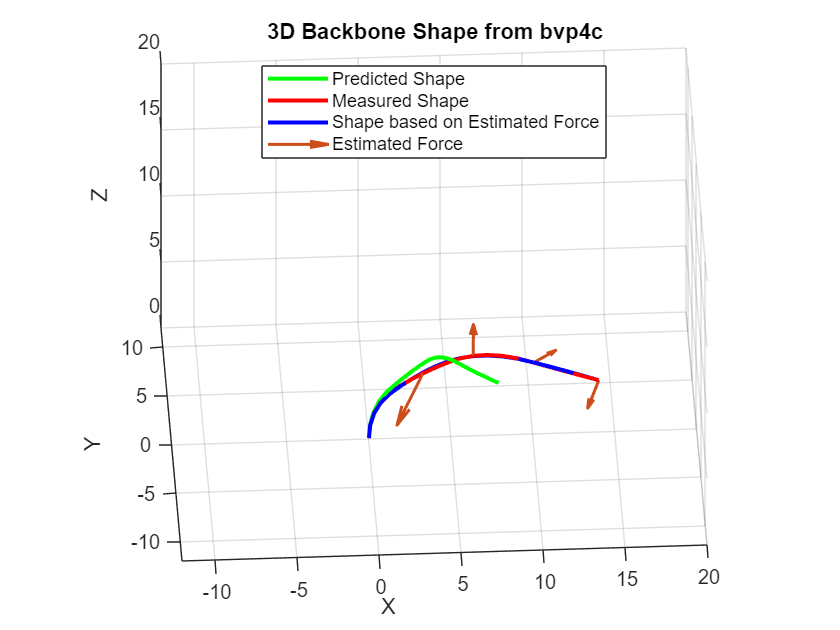



%Post processing
% Forces at the N_d estimation points (3 x N_d)
f_dist_est_d = reshape(x_est, 3, N_d);

% f_dist_est_d = [0 0 0 0 0 0
%                 0 0 0 0 0 0
%                 0 0 0 0 0 0];

% Build full 3xN force matrix with zeros except at nearest N_d nodes
f_dist_est = zeros(3, N);
force_idxs = zeros(1, N_d);


%This is a bit stupid but the other way didnt work
for i = 1:N_d
    [~, force_idxs(i)] = min(abs(s_force - s_force_d(i)));
    f_dist_est(:, force_idxs(i)) = f_dist_est_d(:, i);
end

%f_dist_est(:,1) = [0;0;0]

% Forward solve
[p_act_2, ~] = bending_3D(EI, GJ, r, N,m, ...
    L1, L2, L3, ...
    Base_coord, ...
    0, 0, 0, ...
    Mx, My, Mz, ...
    s_force, f_dist_est, ...  
    ploton);

% --- Plot shapes ---
figure
plot3(p_pred(1,:), p_pred(2,:), p_pred(3,:), 'g-', 'LineWidth', 2); hold on;
plot3(p_act(1,:),  p_act(2,:),  p_act(3,:),  'r-', 'LineWidth', 2);
plot3(p_act_2(1,:), p_act_2(2,:), p_act_2(3,:), 'b-', 'LineWidth', 2);

title('Initial (Zero-Force) Curved Shape');

% --- Plotting distributed force arrows at the N_d locations only ---
max_arrow_length = 4;  
mag_nd = vecnorm(f_dist_est_d, 2, 1);             % 1 x N_d
max_force_mag = max(mag_nd) + 1e-9;               % avoid /0
scale_factor = max_arrow_length / max_force_mag;

for j = 1:N_d
    idx = force_idxs(j);                           % nearest backbone node
    pos = p_act_2(:, m*idx);
    f_vec = f_dist_est_d(:, j);

    f_mag = mag_nd(j);
    if f_mag > 0
        f_dir = f_vec / f_mag;
        L = scale_factor * f_mag;
        quiver3(pos(1), pos(2), pos(3), ...
                L*f_dir(1), L*f_dir(2), L*f_dir(3), ...
                'Color', [0.8 0.3 0.1], ...
                'LineWidth', 1.5, ...
                'MaxHeadSize', 2);
    end
end

xlabel('X'); ylabel('Y'); zlabel('Z');
grid on; axis equal;
xlim([-12 20]); ylim([-12 12]); zlim([0 20]);
title('3D Backbone Shape from bvp4c');
legend('Predicted Shape','Measured Shape','Shape based on Estimated Force','Estimated Force', ...
       'Location', 'best');
hold off

Functions

function err = objective_with_reg_Nd(x, p_target, EI, GJ, r, N, m,N_d, ...
                                  L1,L2,L3, ...
                                  Base_coord, Mx, My, Mz, s_force_d, s_force, lambda)

    % Force values only at N_d points
    f_dist_vec_d = reshape(x, 3, N_d);

    % Make a full N-point force array of zeros
    f_dist_vec_full = zeros(3, N);
    
    % Map each of the N_d estimated forces to the nearest s_force index
    for i = 1:N_d
        [~, idx] = min(abs(s_force - s_force_d(i)));
        f_dist_vec_full(:, idx) = f_dist_vec_d(:, i);
    end

    % Pass to bending_3D
    [p_pred, ~] = bending_3D(EI, GJ, r, N,m, ...
                         L1, L2, L3, ...
                         Base_coord, ...
                         0, 0, 0, ...
                         Mx, My, Mz, ...
                         s_force, f_dist_vec_full, false);

    % Residuals
    data_residual = p_pred(:) - p_target(:);

    % Regularization (on the reduced N_d vector)
    f_ddx = f_dist_vec_d(:,1:end-2) - 2*f_dist_vec_d(:,2:end-1) + f_dist_vec_d(:,3:end);
    reg_penalty = lambda * f_ddx(:);

    err = [data_residual; reg_penalty];
end

%Main function, gives deformed shape based on input force/moment and
%initial shape
function [p_def,p_init] = bending_3D(EI,GJ,r,N,m,L1,L2,L3,Base_coord,Fx,Fy,Fz,Mx,My,Mz,s_force,f_dist_vec,ploton)



    % Build distributed_force_fun from f_dist_vec & s_force if provided
    if isa(f_dist_vec, 'function_handle')
        % f_dist_vec is already a function, use directly
        distributed_force_fun = f_dist_vec;
        %f_vals = distributed_force_fun(s_vals);
        %f_dist_integral = trapz(s_vals, f_vals, 2); % integrate along columns, result 3 x 1

    elseif ~isempty(f_dist_vec) && ~isempty(s_force)
        % f_dist_vec is numeric matrix
        
        distributed_force_fun = @(s) interp1(s_force, f_dist_vec', s, 'linear', 'extrap')';
   
       
    else
        distributed_force_fun = @(s) [0; 0; 0];
        

    end

    % Generate curvature and segment info
    
    % Initialize position array
    
    kappa0_vals = zeros(3,m*N);
    theta_init = zeros(m,N);

    
  
    
    
    
    params.distributed_force_fun = distributed_force_fun;
    %Update initial shape integration to accumulate bending angle linearly
   
    
    % External load applied at tip in global frame
    Fext = [Fx; Fy; Fz];    % force in X and Z directions
    Mext = [Mx; My; Mz];    % zero applied tip moment
    
    
    % Boundary conditions
    p_base = [0;0;0]; %Can change this later
    R_base = eye(3);
    n_tip = Fext;       % internal force at tip balances applied external force (Newton 3rd law)
    m_tip = Mext;       % internal moment at tip balances applied moment
    Kb = EI * eye(3);    % bending stiffness matrix (can be anisotropic)
    Kt = GJ;             % torsional stiffness scalar
    
    
    %Define Parameters for helper functions
    params.Kb = Kb;
    params.Kt = Kt;
    params.Fext = Fext;
    params.Mext = Mext;
    params.p_base = p_base;
    params.R_base = R_base;

    s_vals = zeros(N*m,1);
    max_s = 0;
    
    for i = 1:m
        [T, curvature, Lck, beta, theta] = ...
            gen_transform_2(L1(i), L2(i), L3(i), r, Base_coord);
        s_vals((N*(i-1)+1):N*i) = linspace(0, Lck, N)+max_s;
        max_s = max(s_vals);
        % Angle functions representing intrinsic curvature (constant curvature)
        theta_init(i,:) = theta * ones(N,1);               % Constant bending direction
        %Compute curvature magnitude
        curvature_magnitude = beta / Lck;  % beta = total bending angle, radians; Lck = length
        %Use constant curvature magnitude for intrinsic curvature
        kappa0_vals(:,(N*(i-1)+1):N*i) = [ ...
            curvature_magnitude * cos(theta_init(i,:)-pi/2);   % no -pi/2 shift here
            curvature_magnitude * sin(theta_init(i,:)-pi/2);
            zeros(1, N)];
        
    end
    
    L = sum((L1+L2+L3))/3;
    s_vals = linspace(0,L,m*N);
    

    params.kappa0_fun = @(s) interp1(s_vals', kappa0_vals', s, 'linear', 'extrap')';
    params.n_tip = n_tip;
    params.m_tip = m_tip;
  
    % Initial guess
    %solinit = bvpinit(s_vals', @(s) cosserat_rod_guess(s, params));
    solinit = bvpinit(s_vals, @(s) cosserat_rod_guess(s, params));

    
    % Solve BVP
    sol = bvp4c(@(s,y) cosserat_rod_ode(s,y,params), @(ya,yb) cosserat_rod_bc(ya,yb,params), solinit);
    s_sol = s_vals';
    y_sol = deval(sol, s_sol);
    %define deformed points
    p_def = y_sol(1:3,:);
    
    if ploton == true
        
        %I am going to be lazy here
        params2.distributed_force_fun = @(s) [0; 0; 0];
        params2.Kb = Kb;
        params2.Kt = Kt;
        params2.Fext = [0;0;0];
        params2.Mext = [0;0;0];
        params2.p_base = p_base;
        params2.R_base = R_base;
        params2.kappa0_fun = @(s) interp1(s_vals', kappa0_vals', s, 'linear', 'extrap')';
        params2.n_tip = [0;0;0];
        params2.m_tip = [0;0;0];
        solinit2 = bvpinit(s_vals, @(s) cosserat_rod_guess(s, params2));
        sol2 = bvp4c(@(s,y) cosserat_rod_ode(s,y,params2), @(ya,yb) cosserat_rod_bc(ya,yb,params2), solinit2);
        s_sol2 = s_vals';
        y_sol2 = deval(sol2, s_sol2);
        %define deformed points
        p_init = y_sol2(1:3,:);
        
        % Plot deformed shape
        plot3(p_def(1,:), p_def(2,:), p_def(3,:), 'b-', 'LineWidth', 2);
        hold on;
        
        % Plot initial curved shape
        plot3(p_init(1,:), p_init(2,:), p_init(3,:), 'r-', 'LineWidth', 2);
        
        title('Initial (Zero-Force) Curved Shape');
        % Applied force arrow
        quiver3(p_def(1,end), p_def(2,end), p_def(3,end), Fx/sqrt(Fx^2+Fy^2+Fz^2), Fy/sqrt(Fx^2+Fy^2+Fz^2), Fz/sqrt(Fx^2+Fy^2+Fz^2), ...
            'Color', 'green', 'LineWidth', 2, 'AutoScaleFactor', 1, 'MaxHeadSize', 10);
        
        
        %Plotting distributed force
         % Plot distributed forces along the rod
        %force_scale = .5;  % adjust scale for visibility
        num_force_vectors = m*N;  % number of force vectors to plot
        idxs = round(linspace(1, N, num_force_vectors));
         % Evaluate distributed force magnitude at multiple points
        f_mags = zeros(1, length(idxs));
        for j = 1:length(idxs)
            s = s_vals(idxs(j));
            f_mags(j) = norm(distributed_force_fun(s));
        end
    
        % Determine a global scale factor so arrows are visually reasonable
        max_arrow_length = 2;  % max arrow size in plot units
        max_force_mag = max(f_mags) + 1e-6;  % avoid divide-by-zero
        scale_factor = max_arrow_length / max_force_mag;
        
         % Plot each arrow
        for j = 1:length(idxs)
            i = idxs(j);
            s = s_vals(j);
            pos = p_def(:, j);
            f_vec = distributed_force_fun(s);
    
            % Normalize direction, scale by local magnitude
            f_mag = norm(f_vec);
            f_dir = f_vec / (f_mag + 1e-6);  % unit vector
            arrow_length = scale_factor * f_mag;
    
            % Plot arrow
            quiver3(pos(1), pos(2), pos(3), ...
                    arrow_length * f_dir(1), ...
                    arrow_length * f_dir(2), ...
                    arrow_length * f_dir(3), ...
                    'Color', [0.8 0.3 0.1], ...
                    'LineWidth', 1.5, ...
                    'MaxHeadSize', 2);
        end


        xlabel('X'); ylabel('Y'); zlabel('Z');
        grid on; axis equal;
        xlim([-12 12])
        ylim([-12 12])
        zlim([0 16])
        title('3D Backbone Shape from bvp4c');
        legend('Deformed Shape','Initial Shape',  'Applied Force', 'Distributed Force','Location', 'best');
        
        
        hold off
    else

        p_init = 0;
    
    end
end




%Helper function that makes skew symetric matrix
function S = skew(v)
    S = [   0   -v(3)  v(2);
          v(3)    0   -v(1);
         -v(2)  v(1)    0 ];
end

%Set of ODEs which determine shape under a force, based on Cosserat rod
%theory
%Right now, this ignores twist
function dy = cosserat_rod_ode(s, y, params)
    % Unpack parameters
    Kb = params.Kb;
    %kappa0 = params.kappa0;

    % Unpack state vector
    p = y(1:3);
    R = reshape(y(4:12), 3, 3);  % 3x3 rotation matrix
    n = y(13:15);                % internal force
    m = y(16:18);                % internal moment

    % Tangent vector is d3 (third column of R)
    t = R(:,3);

    % Calculate curvature vector
    kappa0 = params.kappa0_fun(s);  % dynamically evaluated
    kappa = Kb \ (m - Kb * kappa0);

    % Derivatives
    dp_ds = t;                            % position derivative
    dR_ds = R * skew(kappa);             % rotation derivative
    
     % Distributed force per unit length
    f_dist = params.distributed_force_fun(s);  % [fx; fy; fz] at position s
    
    dn_ds = -f_dist;              % internal force equilibrium
    dm_ds = -cross(t, n);         % internal moment equilibrium
    
    
    %dn_ds = [0; 0; 0];                   % no distributed forces (lumped tip only)
    %dm_ds = -cross(t, n);               % internal moment equilibrium

    % Pack derivatives
    dy = zeros(18,1);
    dy(1:3) = dp_ds;
    dy(4:12) = reshape(dR_ds, 9, 1);
    dy(13:15) = dn_ds;
    dy(16:18) = dm_ds;
    
    %fprintf('s = %.4f, f = [%.3e %.3e %.3e]\n', s, params.distributed_force_fun(s));
end

%Boundary conditions for ODE solver
function res = cosserat_rod_bc(ya, yb, params)
    % Boundary conditions at base (s=0) and tip (s=L)

    p_base = params.p_base;
    R_base = params.R_base;
    n_tip = params.n_tip;
    m_tip = params.m_tip;

    res = [ ...
        ya(1:3) - p_base; ...          % base position fixed
        ya(4:12) - reshape(R_base,9,1); ... % base orientation fixed
        yb(13:15) - n_tip; ...         % tip internal force = external applied force
        yb(16:18) - m_tip ...          % tip internal moment = external applied moment
    ];
end


%Initial guess for ODE solver
function yinit = cosserat_rod_guess(s, params)
    % Interpolate intrinsic curvature at s
    kappa0 = params.kappa0_fun(s);
    
    % Integrate to get tangent vector (approximate)
    % Assuming constant theta and beta along s for simplicity
    beta_val = norm(kappa0) * s;  % angle of bending up to s
    if beta_val < 1e-6
        tangent = [0;0;1]; % nearly straight
    else
        theta_val = atan2(kappa0(2), kappa0(1));
        tangent = [sin(beta_val)*cos(theta_val);
                   sin(beta_val)*sin(theta_val);
                   cos(beta_val)];
    end
    
    % Approximate position
    p = tangent * s; % linear approx; you can improve by integrating

    % Approximate rotation: identity for simplicity
    R = eye(3);

    % Guess internal forces and moments
    n = params.n_tip;
    m = params.m_tip;

    yinit = [p; reshape(R,9,1); n; m];
end

%Kinematics function 
function [T_k, rho_k,L_ck,beta_k,theta_k] = ...
    gen_transform_2(L_k1, L_k2, L_k3, r, T_prev)

    phi_kj = 0; % fixed angle

    % calculate length
    L_ck = (L_k1 + L_k2 + L_k3)/3;
    beta_k = 2*sqrt(L_k1^2 + L_k2^2 + L_k3^2 - L_k1*L_k2 - L_k1*L_k3 - L_k2*L_k3)/(3*r);
    theta_k = atan2(3*(L_k2 - L_k3), sqrt(3)*(L_k2 + L_k3 - 2*L_k1));

    rho_k = beta_k/L_ck; % Curvature calc

    % Rotation matrix
    ct = cos(theta_k);
    st = sin(theta_k);
    cb = cos(beta_k);
    sb = sin(beta_k);

    R_k = [
        cb*ct^2 + st^2,      (cb-1)*ct*st,       ct*sb;
        (cb-1)*ct*st,        ct^2 + cb*st^2,     st*sb;
        -ct*sb,              -st*sb,             cb
    ];

    % Position vector
    P_k = (1/rho_k) * [(1-cb)*ct; (1-cb)*st; sb];

    % Transformation matrix
    T_k = [R_k P_k; 0 0 0 1];
    if abs(rho_k) < 1e-6
        T_k = [1 0 0 0
               0 1 0 0
               0 0 1 L_ck
               0 0 0 1];
    end
    
end